Nlist = [10000, 5000, 2500, 1000, 500, 250, 100, 50, 25, 10];
Elist = [4.3541e-11, 1.1945e-11, 4.0203e-12, 7.8892e-13, 3.53118e-13, ...
    1.2090e-13, 3.8025e-14, 1.6043e-14, 5.4956e-15, 1.7764e-15]

Elist = 	1.0e+-10 *

    0.4354    0.1195    0.0402    0.0079    0.0035    0.0012    0.0004    0.0002    0.0001    0.0000


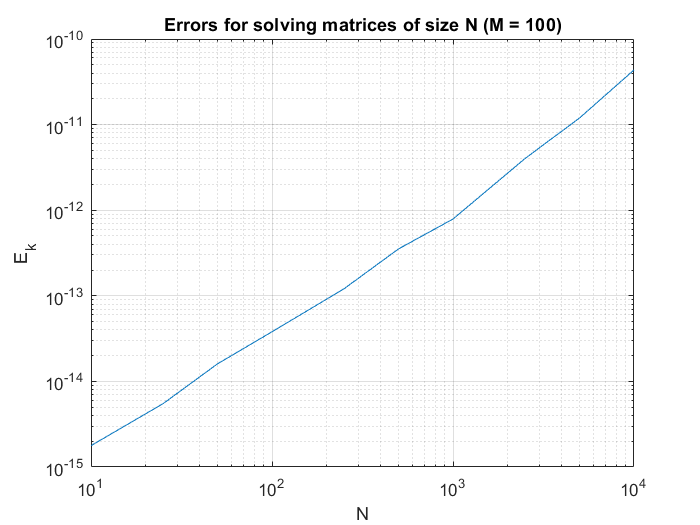

loglog(Nlist, Elist)
title 'Errors for solving matrices of size N (M = 100)'
xlabel 'N'
ylabel 'E_k'
grid on

p = polyfit(log10(Nlist), log10(Elist), 1)

p =     1.4433  -16.2879


yp = polyval(p, log10(Nlist))

yp =   -10.5148  -10.9492  -11.3837  -11.9580  -12.3925  -12.8270  -13.4013  -13.8358  -14.2703  -14.8446


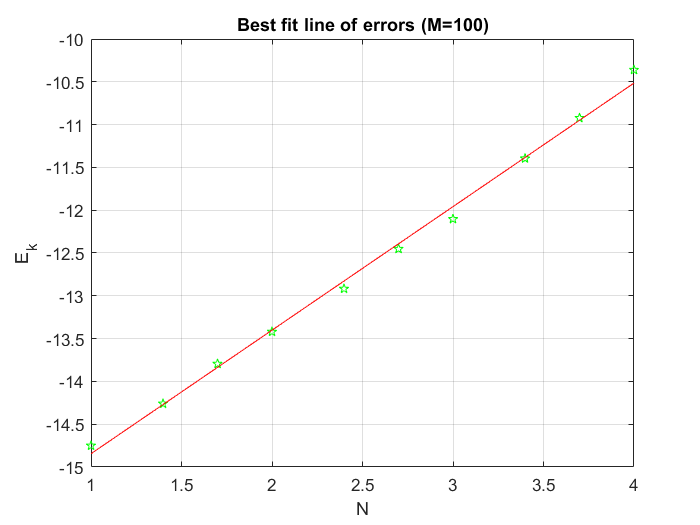

plot(log10(Nlist), log10(Elist),'pg')
hold on
plot(log10(Nlist), yp, '-r')
grid on
xlabel 'N'
ylabel 'E_k'
title 'Best fit line of errors (M=100)'
hold off

a = 10.^((0-p(2))/p(1))

y = 	1.0e+04 *

    1.4417    0.7200    0.3592    0.1427    0.0705    0.0345    0.0128    0.0056    0.0020   -0.0002


a = 1.9286e+11